FIK_st.name='FKL'; %--> to ask
FIK_st.lat=35.34;
FIK_st.lon=25.67;
FIK_st.alt=150;
FIK_st.env='coast';
FIK_st.footp='RB';
FKL_st.name='FKL'; %--> to ask
FKL_st.lat=35.34;
FKL_st.lon=25.67;
FKL_st.alt=150;
FKL_st.env='coast';
FKL_st.footp='RB';


FIK_rd=read_betsy('FIK_2004_2017',FIK_st.name);

fik_AE3_2011 =FIK_AE3_importfile('Finokalia aethalometer dry 2011 - 2018.xlsx','2011 AE31',4,8763);
fik_AE3_2012 = FIK_AE3_importfile('Finokalia aethalometer dry 2011 - 2018.xlsx','2012 AE31',4,8763);
fik_AE3_2013 = FIK_AE3_importfile('Finokalia aethalometer dry 2011 - 2018.xlsx','2013 AE31',4,8763);
fik_AE3_2014 = FIK_AE3_importfile('Finokalia aethalometer dry 2011 - 2018.xlsx','2014 AE31',4,8763);
fik_AE3_2014V2 = FIK_AE3_importfile('Finokalia aethalometer dry 2011 - 2018.xlsx','2014 AE33',4,8763);

fik_AE3_2015 = FIK_AE3_importfile('Finokalia aethalometer dry 2011 - 2018.xlsx','2015 AE33',4,8763);
fik_AE3_2016 = FIK_AE3_importfile('Finokalia aethalometer dry 2011 - 2018.xlsx','2016 AE33',4,8763);
fik_AE3_2017 = FIK_AE3_importfile('Finokalia aethalometer dry 2011 - 2018.xlsx','2017 AE33',4,8763);
fik_AE3_2018 = FIK_AE3_importfile('Finokalia aethalometer dry 2011 - 2018.xlsx','2018 AE33',4,8763);

fik_AE22_2003=FIK_AE22_importfile('Finokalia aethalometer wet and dry 2003 - 2010.xlsx','2003 AE22',5,8763);
fik_AE22_2004=FIK_AE22_importfile('Finokalia aethalometer wet and dry 2003 - 2010.xlsx','2004 AE22',5,8763);
fik_AE22_2005=FIK_AE22_importfile('Finokalia aethalometer wet and dry 2003 - 2010.xlsx','2005 AE22',5,8763);
fik_AE22_2006=FIK_AE22_importfile('Finokalia aethalometer wet and dry 2003 - 2010.xlsx','2006 AE22',5,8763);
fik_AE22_2007=FIK_AE22_importfile('Finokalia aethalometer wet and dry 2003 - 2010.xlsx','2007 AE22',5,8763);
fik_AE22_2008=FIK_AE22_importfile('Finokalia aethalometer wet and dry 2003 - 2010.xlsx','2008 AE22',5,8763);
fik_AE22_2009=FIK_AE22_importfile('Finokalia aethalometer wet and dry 2003 - 2010.xlsx','2009 AE22',5,8763);
fik_AE22_2010=FIK_AE22_importfile('Finokalia aethalometer wet and dry 2003 - 2010.xlsx','2010 AE22',5,8763);

fik_PSAP=FIK_PSAP_importfile('Finokalia psap wet 2000 - 2002.xlsx','Φύλλο1',5,18075);

fik_AE31=[fik_AE3_2011;fik_AE3_2012;fik_AE3_2013;fik_AE3_2014];
fik_AE33=[fik_AE3_2014V2;fik_AE3_2015;fik_AE3_2016;fik_AE3_2017;fik_AE3_2018];
fik_AE22=[fik_AE22_2003;fik_AE22_2004;fik_AE22_2005;fik_AE22_2006;fik_AE22_2007;fik_AE22_2008;fik_AE22_2009;fik_AE22_2010];

AE22=timetable(fik_AE22.VarName4, fik_AE22.black_carbonngm3Wavelength370nm,fik_AE22.black_carbonngm3Wavelength880nm);
AE31=timetable(fik_AE31.VarName4, fik_AE31.equivalent_black_carbonngm1, fik_AE31.equivalent_black_carbonngm2,fik_AE31.equivalent_black_carbonngm3,fik_AE31.equivalent_black_carbonngm4,fik_AE31.equivalent_black_carbonngm5,fik_AE31.equivalent_black_carbonngm6,fik_AE31.equivalent_black_carbonngm7);
ind=isnat(AE31.Time);
AE31(ind,:)=[];
AE33=timetable(fik_AE33.VarName4, fik_AE33.bypass_fraction3, fik_AE33.sensing_zero_signal4,fik_AE33.reference_beam_signal4,fik_AE33.attenuation_coefficient4,fik_AE33.reference_zero_signal5,fik_AE33.equivalent_black_carbonngm6,fik_AE33.sensing_beam_signal6);
ind=isnat(AE33.Time);
AE33(ind,:)=[];
AE3=[AE31;AE33];
PSAP=timetable(fik_PSAP.TimeUTC2,fik_PSAP.Mm);

% nommer les variables
AE3.Properties.VariableNames={'Ba1_A'; 'Ba2_A'; 'Ba3_A' ;'Ba4_A' ;'Ba5_A' ;'Ba6_A' ;'Ba7_A'};
AE22.Properties.VariableNames={'Ba1_A'; 'Ba6_A'};
PSAP.Properties.VariableNames={'BaG_A'};
%enlever missing > 1e4
names3=fieldnames(AE3);
c= startsWith(names3,'Ba');
names3=names3(c);
for i=1:length(names3)
    ind=AE3.(names3{i})>9999;
    AE3.(names3{i})(ind)=NaN;
end

names22=fieldnames(AE22);
c= startsWith(names22,'Ba');
names22=names22(c);
for i=1:length(names22)
    ind=AE22.(names22{i})>9999;
    AE22.(names22{i})(ind)=NaN;
end

%PSAP abs sinon BC
cte = 14625e-9/3.5;

AE3.Ba1_A= cte * AE3.Ba1_A.*1e6./ 370;
AE3.Ba2_A= cte * AE3.Ba2_A.*1e6./ 470;
AE3.Ba3_A= cte * AE3.Ba3_A.*1e6./ 520;
AE3.Ba4_A= cte * AE3.Ba4_A.*1e6./ 590;
AE3.Ba5_A= cte * AE3.Ba5_A.*1e6./ 660;
AE3.Ba6_A= cte * AE3.Ba6_A.*1e6./ 880;
AE3.Ba7_A= cte * AE3.Ba7_A.*1e6./ 950;

AE22.Ba1_A= cte * AE22.Ba1_A.*1e6./ 370;
AE22.Ba6_A= cte * AE22.Ba6_A.*1e6./ 880;
%median diurnale
%delete à la mains les NaT dans AE22 car j'ai fait lire plus que le nb de
%lignes nécessaires
ind=isnat(AE22.Time);
AE22(ind,:)=[];

% % ind=isnat(AE3.Time);
% % AE3(ind,:)=[];
TT=synchronize(AE3,AE22);
FIK_rd_mco=synchronize(TT,PSAP);

% % %IN Mm-1
% % names=fieldnames(FIK_rd_mco);
% % c=startsWith(names,'Ba')==1 & contains(names,'G')==0;
% % namesc=names(c);
% % for i=1:length(namesc)
% %     FIK_rd_mco.(namesc{i})=FIK_rd_mco.(namesc{i}).*1e6;
% % end

% daily mean, apply a data coverage threshold ?
 station_datD=retime(FIK_rd_mco,'daily',@nanmedian);
 station_datN=retime(FIK_rd_mco,'daily','count');
 namesOK=fieldnames(FIK_rd_mco);
CB=startsWith(namesOK,'B');
 SB=namesOK(CB);
 for i=1:length(SB)
 indN=station_datN.(SB{i})<6 ;
 a(i)=sum(indN)*100/sum(~isnan(station_datD.(SB{i})));
 station_datD.(SB{i})(indN)=NaN;
 end
 FIK_rd_mco2=station_datD;

datevec(FIK_rd_mco2.Time(1))

ans =         2000           7           9           1          30           0


datevec(FIK_rd_mco2.Time(end))

ans = 	1.0e+03 *

    2.0180    0.0120    0.0310    0.0230    0.0300    0.0001


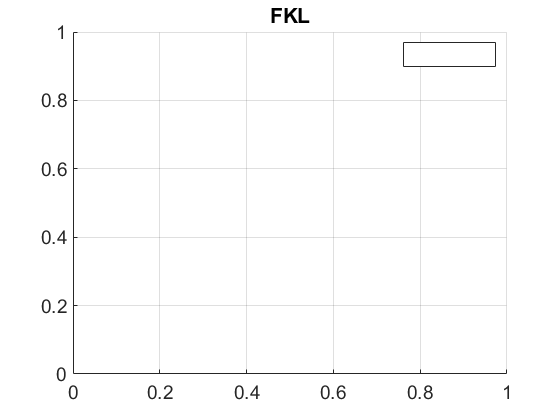

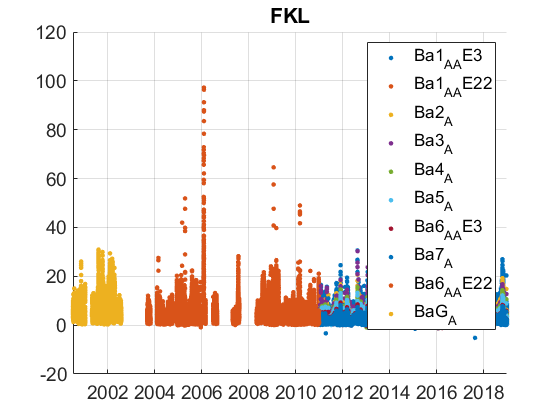

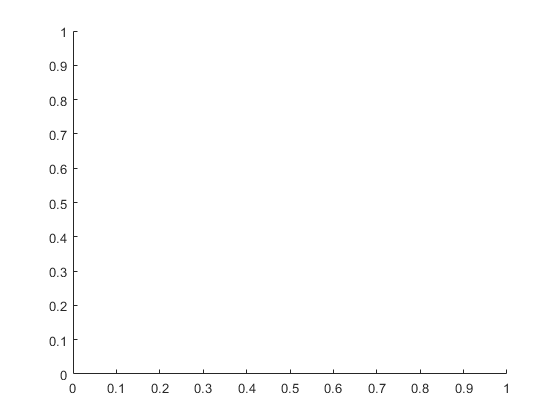

%prctile(FIK_rd.U_S,[5 50 95])
plotFigControl(FIK_rd_mco2,FIK_st.name);

datevec(FIK_rd.Time(1))

ans =         2004           1           2           0           0           0

datevec(FIK_rd.Time(end))

ans =         2015           3          10           0           0           0

prctile(FIK_rd.U_S,[5 50 95])

ans =     6.4500   25.8000   41.1000

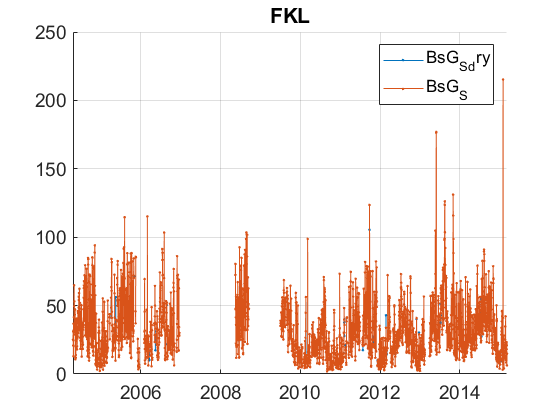

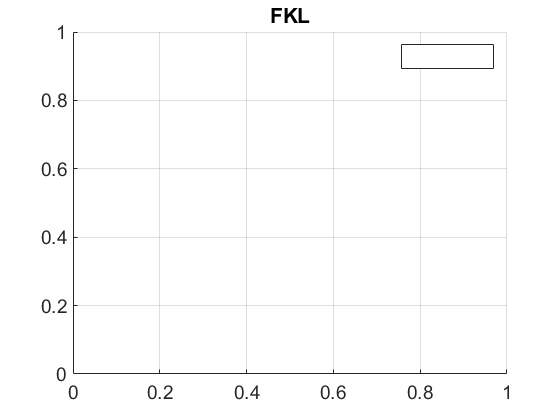

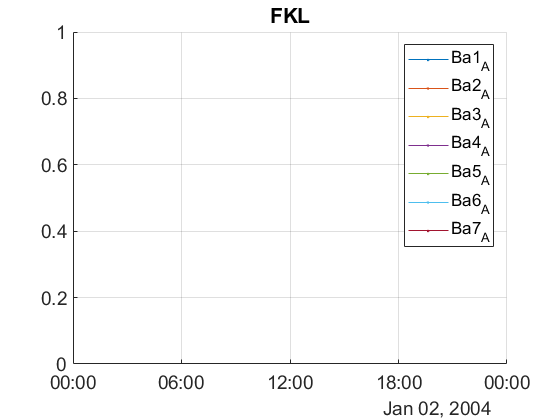

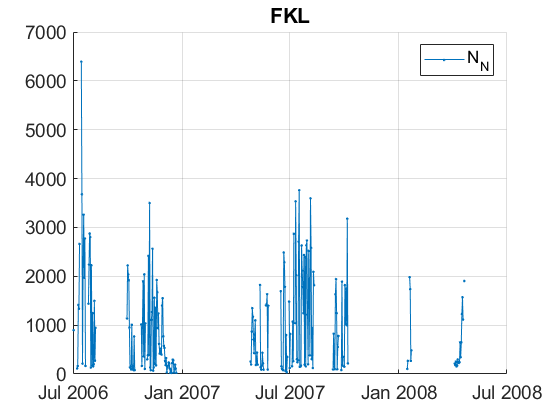

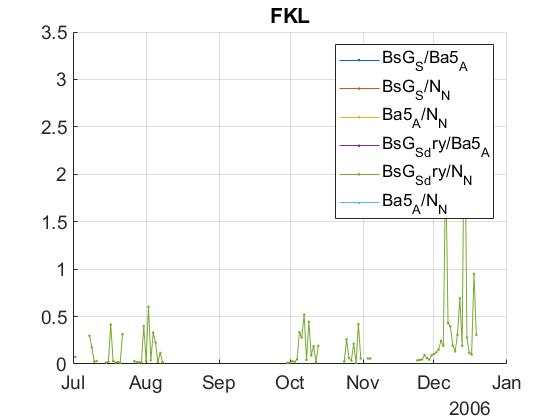

plotFigControl(FIK_rd,FIK_st.name);

% several size cut, NTO OK
% sc: so many instrumental and size cut changes that no homogeneous time
% series is possible
% abs: 2 size cut, max in summer, no negatives


lambdaSC=[450;550;700]*ones(1,4);
lambdaAE=[467;530;660]*ones(1,4);
lambdaAE7=[370 470 520 590 660 880 950];
FIK_cal=compute_exp_SSA(FIK_rd,lambdaSC, lambdaAE);
plotFigControl_cal(FIK_cal,FIK_st.name);

%Questions:
%problems:


FIK_tr=FIK_rd_mco2;
FIK_tr.y=year(FIK_tr.Time);
% begin at the beginning of a year: 2004
%end 2018

P=timerange('2004-01-01','2019-01-01');
FIK_tr=FIK_tr(P,:);
%put AE22 and AE3 together
P1=timerange('2004-01-01','2011-01-01');
FIK_tr.Ba1_A=FIK_tr.Ba1_A_AE3;
FIK_tr.Ba1_A(P1)=FIK_tr.Ba1_A_AE22(P1);
FIK_tr.Ba1_A_AE3=[];
FIK_tr.Ba1_A_AE22=[];

FIK_tr.Ba6_A=FIK_tr.Ba6_A_AE3;
FIK_tr.Ba6_A(P1)=FIK_tr.Ba6_A_AE22(P1);
FIK_tr.Ba6_A_AE3=[];
FIK_tr.Ba6_A_AE22=[];
% 880 is better for difference between AE31 and AE33
%use it for the trend analysis
FIK_tr.Ba1_A=[];
FIK_tr.Ba2_A=[];
FIK_tr.Ba3_A=[];
FIK_tr.Ba4_A=[];
FIK_tr.Ba5_A=[];
FIK_tr.Ba7_A=[];
%PSAP: not possible to homogeneise
FIK_tr.BaG_A=[];
FKL_tr=FIK_tr; FKL_st=FIK_st;

Iterating trend, loop:2, trend: -8.3739e-05/day = -0.030586/year
Iterating trend, loop:3, trend: -8.2014e-05/day = -0.029956/year
Iteration stopped, trend: -8.2013e-05/day = -0.029955/year
Final estimate on noise autocorrelation=0.08791, Noise standard deviation:0.67765
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-0.0001733 -1.0792e-05]/day = [-0.063299  -0.0039417]/yr
Round:200/500, Trend BCI: [-0.00016716 -3.7689e-06]/day = [-0.061055  -0.0013766]/yr
Round:300/500, Trend BCI: [-0.00016716  -8.579e-06]/day = [-0.061055  -0.0031335]/yr
Round:400/500, Trend BCI: [-0.00016197  1.2691e-06]/day = [-0.059159  0.00046354]/yr
Round:500/500, Trend BCI: [-0.00016665  -3.073e-06]/day = [-0.06087  -0.0011224]/yr
Trend BCI: [-0.00016665  -3.073e-06]/day = [-0.06087  -0.0011224]/yr


Iterating trend, loop:2, trend: -8.3407e-05/day = -0.030464/year
Iterating trend, loop:3, trend: -8.0184e-05/day = -0.029287/year
Iteration stopped, trend: -8.0183e-05/day = -0.029287/year
Final estimate on noise autocorrelation=0.10172, Noise standard deviation:0.60814
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-0.00016882  2.5548e-06]/day = [-0.061662  0.00093315]/yr
Round:200/500, Trend BCI: [-0.00017666  1.1638e-05]/day = [-0.064525   0.0042508]/yr
Round:300/500, Trend BCI: [-0.00018535  2.5213e-05]/day = [-0.067698   0.0092089]/yr
Round:400/500, Trend BCI: [-0.00019341  3.0074e-05]/day = [-0.070643    0.010984]/yr
Round:500/500, Trend BCI: [-0.00020164  3.5107e-05]/day = [-0.073649    0.012823]/yr
Trend BCI: [-0.00020164  3.5107e-05]/day = [-0.073649    0.012823]/yr
Iterating trend, loop:2, trend: 2.9813e-06/day = 0.0010889/year
Iterating trend, loop:3, trend: 6.1294e-06/day = 0.0022388/year
Iteration stopped, trend: 6.1355e-06/day = 0.002241/year
Final estimate on noise 

Iterating trend, loop:2, trend: -0.00017022/day = -0.062172/year
Iterating trend, loop:3, trend: -0.00016577/day = -0.060547/year
Iteration stopped, trend: -0.00016575/day = -0.06054/year
Final estimate on noise autocorrelation=0.063385, Noise standard deviation:0.60435
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-0.00027405 -7.6411e-06]/day = [-0.1001  -0.0027909]/yr
Round:200/500, Trend BCI: [-0.00027006 -3.5375e-05]/day = [-0.098638   -0.012921]/yr
Round:300/500, Trend BCI: [-0.00027015 -3.8634e-05]/day = [-0.098671   -0.014111]/yr
Round:400/500, Trend BCI: [-0.00027541 -3.7548e-05]/day = [-0.10059   -0.013714]/yr
Round:500/500, Trend BCI: [-0.00027246 -4.0495e-05]/day = [-0.099515   -0.014791]/yr
Trend BCI: [-0.00027246 -4.0495e-05]/day = [-0.099515   -0.014791]/yr


Iterating trend, loop:2, trend: -0.00036154/day = -0.13205/year
Iterating trend, loop:3, trend: -0.00039299/day = -0.14354/year
Iteration stopped, trend: -0.00039314/day = -0.1436/year
Final estimate on noise autocorrelation=-0.17629, Noise standard deviation:0.68588
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-0.00026899+6.5271e-07i   -0.0004985+1.7822e-06i]/day = [-0.098248+0.0002384i     -0.18208+0.00065093i]/yr
Round:200/500, Trend BCI: [-0.00028439-1.1273e-06i   -0.0004891+8.3975e-08i]/day = [-0.10387-0.00041174i     -0.17864+3.0672e-05i]/yr
Round:300/500, Trend BCI: [-0.00026968+9.6432e-07i   -0.0004927+3.6916e-07i]/day = [-0.098501+0.00035222i     -0.17996+0.00013484i]/yr
Round:400/500, Trend BCI: [-0.00028262+1.3857e-06i   -0.0004927+3.6916e-07i]/day = [-0.10323+0.00050612i     -0.17996+0.00013484i]/yr
Round:500/500, Trend BCI: [-0.00028452+1.0076e-06i  -0.00049712+9.5721e-07i]/day = [-0.10392+0.00036804i     -0.18157+0.00034962i]/yr
Trend BCI: [-0.00028452+1.0076e-06i 

Iterating trend, loop:2, trend: -0.00021486/day = -0.078478/year
Iterating trend, loop:3, trend: -0.00022307/day = -0.081478/year
Iteration stopped, trend: -0.0002231/day = -0.081486/year
Final estimate on noise autocorrelation=-0.073652, Noise standard deviation:0.70797
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-0.00011909-4.0325e-07i   -0.0003671+8.3411e-07i]/day = [-0.043497-0.00014729i     -0.13408+0.00030466i]/yr
Round:200/500, Trend BCI: [-0.00011042+1.274e-07i  -0.00035404-1.2427e-06i]/day = [-0.040332+4.6534e-05i      -0.12931-0.0004539i]/yr
Round:300/500, Trend BCI: [-0.00011042+1.274e-07i  -0.00035404-1.2427e-06i]/day = [-0.040332+4.6534e-05i      -0.12931-0.0004539i]/yr
Round:400/500, Trend BCI: [-0.00011179+4.7099e-07i  -0.00034714-7.1542e-07i]/day = [-0.04083+0.00017203i     -0.12679-0.00026131i]/yr
Round:500/500, Trend BCI: [-0.00010754+1.9565e-07i  -0.00033909+7.4103e-07i]/day = [-0.039279+7.146e-05i     -0.12385+0.00027066i]/yr
Trend BCI: [-0.00010754+1.9565e-

Iterating trend, loop:2, trend: -8.8131e-05/day = -0.03219/year
Iterating trend, loop:3, trend: -8.7514e-05/day = -0.031965/year
Iteration stopped, trend: -8.7514e-05/day = -0.031964/year
Final estimate on noise autocorrelation=-0.028134, Noise standard deviation:0.71372
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-1.3036e-06+5.7828e-08i  -0.00020454+6.9435e-08i]/day = [-0.00047615+2.1122e-05i    -0.074709+2.5361e-05i]/yr
Round:200/500, Trend BCI: [1.1145e-07+8.525e-08i  -0.00020086+1.8686e-07i]/day = [4.0707e-05+3.1138e-05i    -0.073363+6.8249e-05i]/yr
Round:300/500, Trend BCI: [2.4079e-07-2.355e-07i  -0.00021247+5.1151e-08i]/day = [8.7948e-05-8.6015e-05i    -0.077606+1.8683e-05i]/yr
Round:400/500, Trend BCI: [-2.6729e-08-7.2509e-08i  -0.00021492+6.8676e-08i]/day = [-9.7629e-06-2.6484e-05i      -0.0785+2.5084e-05i]/yr
Round:500/500, Trend BCI: [2.4079e-07-2.355e-07i  -0.00021761+1.8925e-07i]/day = [8.7948e-05-8.6015e-05i    -0.079481+6.9125e-05i]/yr
Trend BCI: [2.4079e-07-2.35

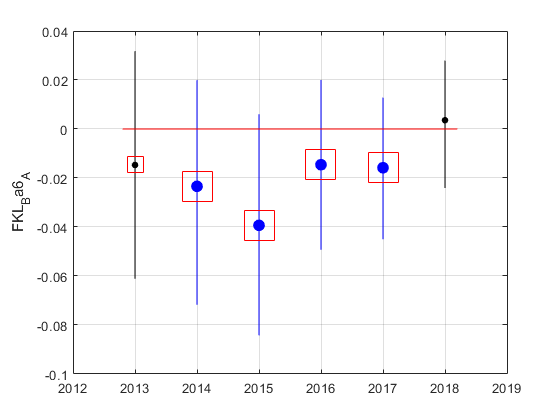

FKL_result = 35×9 table
    station    end_time    length_period    granularity    parameter    instrument    MK_seasonality    method      results   
    _______    ________    _____________    ___________    _________    __________    ______________    ______    ____________
     'FKL'       2017           10            'daily'       'Ba6_A'       'abs'          'y'            'MK'      [1×1 struct]
     'FKL'       2017           10            'daily'       'Ba6_A'       'abs'          'MetSea'       'MK'      [1×1 struct]
     'FKL'       2017           10            'daily'       'Ba6_A'       'abs'          'month'        'MK'      [1×1 struct]
     'FKL'       2017           15 

FKL_result= all_trend_STN(FKL_tr,FKL_st); 

FKL_result_D=FKL_result;